% Load data, make into vectors, drop missing values using local func drop_nan
fluidsdata = xlsread('fluidslab1data.xlsx');
port_no = drop_nan(fluidsdata(:,1));
trdcr_read = drop_nan(fluidsdata(:,2)); % volts
port1_ht = drop_nan(fluidsdata(:,3)); % mm
port1_v = drop_nan(fluidsdata(:,4)); % volts
port5_ht = drop_nan(fluidsdata(:,5)); % mm
port5_v = drop_nan(fluidsdata(:,6)); % volts
port8_ht = drop_nan(fluidsdata(:,7)); % mm
port8_v = drop_nan(fluidsdata(:,8)); % volts
port10_ht = drop_nan(fluidsdata(:,9)); % mm
port10_v = drop_nan(fluidsdata(:,10)); % volts
micro_off = drop_nan(fluidsdata(1,11)); % inches
micro_on = drop_nan(fluidsdata(1,12)); % inches
trdcr_off = drop_nan(fluidsdata(1,13)); % volts
trdcr_on = drop_nan(fluidsdata(1,14)); % volts
p_atm = drop_nan(fluidsdata(1,15)); % kPa
temp = drop_nan(fluidsdata(1,16)); % degrees F

Now  prepare for calibration curve

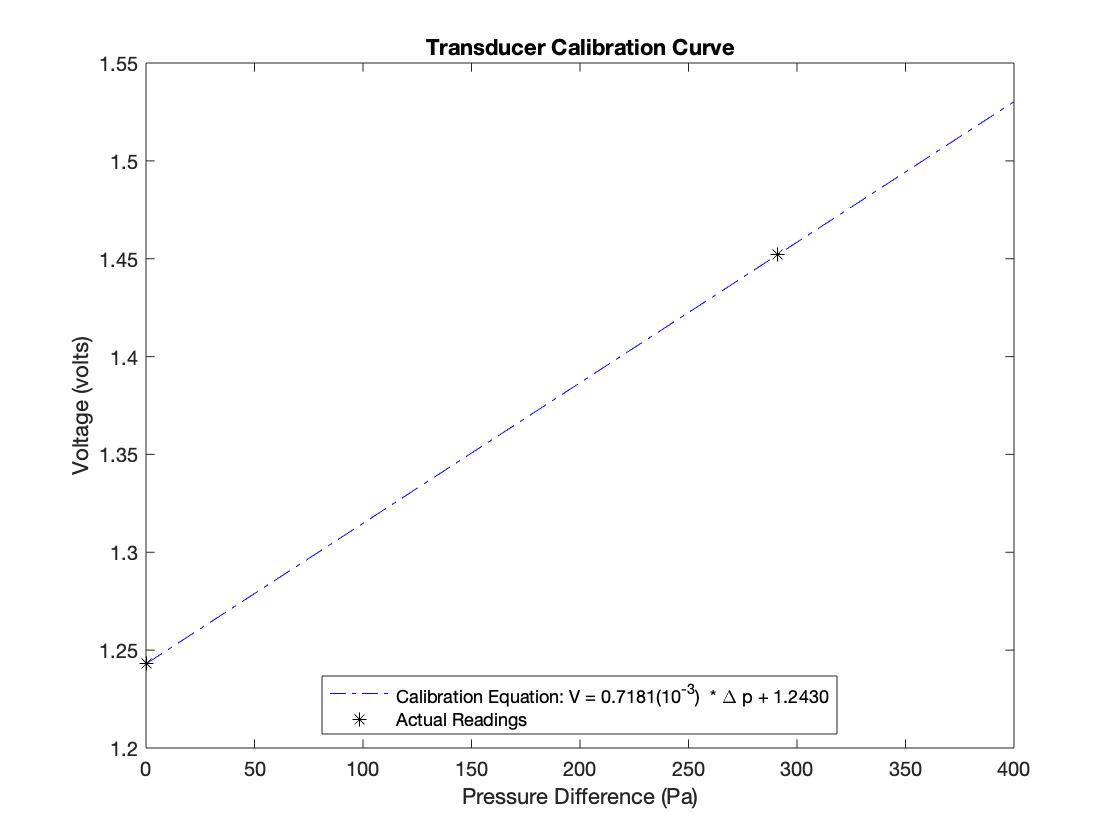

% Convert micrometer readings to meters
micro_read = [micro_off micro_on];
micro_read = inches2m(micro_read);

% Find x-values (pressure difference) for calibration curve
for i = 1:length(micro_read)
    micro_read(i) = 2 * (micro_read(i) - micro_read(1)) * 1000 * 9.81;
    % From appendix, x = 2 * (height delta) * (density water) * (gravity)
end
transducer_read = [trdcr_off trdcr_on];

% Find equation of calibration line
calib = polyfit(micro_read, transducer_read, 1);
calib_equat = sprintf('Calibration Equation: V = %.4f(10^{-3})  * \\Delta p + %.4f', calib(1) * 1000, calib(2));

% Make calibration plot
plot(linspace(0,400,100), polyval(calib, linspace(0,400,100)), 'b-.')
title('Transducer Calibration Curve')
xlabel('Pressure Difference (Pa)')
ylabel('Voltage (volts)')
hold on
plot(micro_read, transducer_read, 'k*')
legend(calib_equat, 'Actual Readings', "Location", "best")
hold off

Now prepare velocity plots

% Convert from voltage to change in pressure using local func del_p
port1_p = del_p(port1_v, calib);
port5_p = del_p(port5_v, calib);
port8_p = del_p(port8_v, calib);
port10_p = del_p(port10_v, calib);

% Calculate velocities at the ports
port1_vel = calc_velocity(port1_p);
port5_vel = calc_velocity(port5_p);
port8_vel = calc_velocity(port8_p);
port10_vel = calc_velocity(port10_p);

% Make plots
plot(port1_vel, port1_ht, 'md') % Port 1
title('Vertical Position vs. Velocity')
xlabel('Velocity (m/s)')
ylabel('Vertical Position (mm)')
hold on 
plot(port5_vel, port5_ht, 'b*') % Port 5
hold on
plot(port8_vel, port8_ht, 'r+') % Port 8
hold on
plot (port10_vel, port10_ht, 'ks') % Port 10

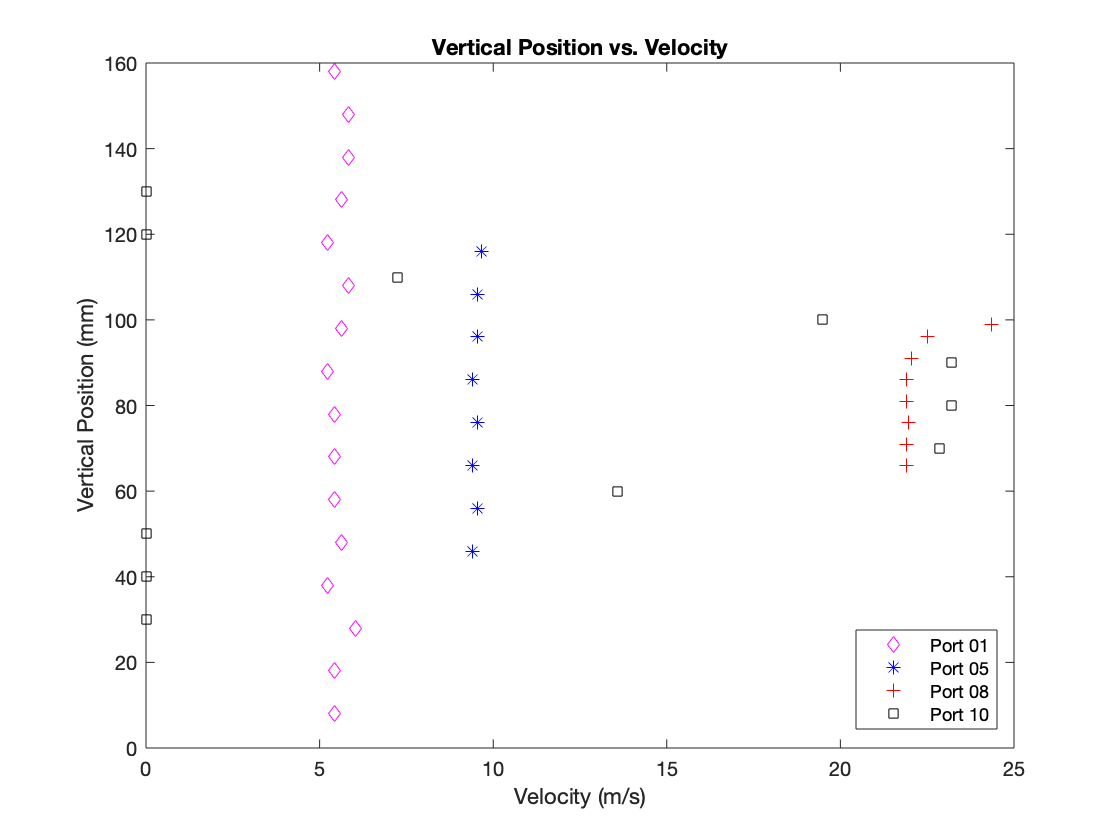

legend('Port 01', 'Port 05', 'Port 08', 'Port 10', "Location", "best")

Now, calculate averare velocities for the ports with measurements

% Find average velocities with ports measured
avel_01 = ave_velocity(port1_vel);
avel_05 = ave_velocity(port5_vel);
avel_08 = ave_velocity(port8_vel);
avel_10 = ave_velocity(port10_vel);
ht_vec = [.165271, .146007, .125988, .107857, .088593, .069707, .050443, .041, .223958, .277455]; % vector of heights 
area_vec = calc_xsarea(ht_vec);

% Calculate flowrate, Q
Q_01 = flow_rate(avel_01, area_vec(1))

Q_01 = 0.1864

Q_05 = flow_rate(avel_05, area_vec(5))

Q_05 = 0.1709

Q_08 = flow_rate(avel_08, area_vec(8))

Q_08 = 0.1847

Q_10 = flow_rate(avel_10, area_vec(10))

Q_10 = 0.6172 + 0.0990i

Q_vec = zeros(1,10) + Q_08;
Q_vec = Q_vec';

% Make ave velocity vector for each port respectively
% Taking Q to be that at Port 8
Ave_Vel_vec = Q_08 ./ area_vec;
Ave_Vel_vec(1) = avel_01;
Ave_Vel_vec(5) = avel_05;
Ave_Vel_vec(10) = 10.9579;
Ave_Vel_vec = Ave_Vel_vec';

% Now calculate hydraulic diameter and Reynolds numbers
per_vec = calc_perim(ht_vec);
Hyd_Diam = calc_hyd_diam(area_vec, per_vec);
Rey_No = calc_rey(Ave_Vel_vec,Hyd_Diam);
Rey_No = Rey_No';

% Now calculate static pressure from final transducer readings
Stat_P = del_p(trdcr_read, calib);
Stat_P = Stat_P * -1; % Pascals, negative because measuring relative to intercept found
Stag_P = calc_stagpress(Stat_P, Ave_Vel_vec); % Pascals

fprintf('%12s%12s%12s%12s%12s%12s', 'Port', 'Ave Vel', 'Rey No', 'Stat P', 'Flow Rt', 'Stag P')

        Port     Ave Vel      Rey No      Stat P     Flow Rt      Stag P

for i = 1:10
    fprintf('%12.3f%12.3f%12.3f%12.3f%12.3f%12.3f\n', port_no(i), Ave_Vel_vec(i), Rey_No(i), Stat_P(i), Q_vec(i), Stag_P(i))
end

       1.000       5.555   68503.096     -25.065       0.185      -6.164
       2.000       6.233   63858.779     -29.243       0.185      -5.450
       3.000       7.223   58456.148     -37.598       0.185      -5.644
       4.000       8.437   52962.534     -48.738       0.185      -5.138
       5.000       9.502   46377.078     -62.663       0.185      -7.363
       6.000      13.055   39017.656     -72.411       0.185      31.973
       7.000      18.040   30380.973    -214.447       0.185     -15.112
       8.000      22.195   25649.275    -316.100       0.185     -14.371
       9.000       4.063   80068.648    -336.988       0.185    -326.876
      10.000      10.958   88149.714    -341.166       0.185    -267.619


function out = drop_nan(x)
% From xlsx file, removes all NaN values
% Format: drop_nan(vector)
x(find(isnan(x))) = [];
out = x;
end

function out = inches2m(x)
% Converts from inches to mm
% Format: inches2mm(inches_vector)
out = x * 0.0254;
end

function out = del_p(x, y)
% Calculates change in pressure (Pa) using voltage readings & first order
% polynomial fit
% Format: del_p(voltage_vector, polyfit_vector)
out = (x - y(2)) / y(1);
end

function out = calc_velocity(x) 
% Calculates the velocity using pressure difference and density of air
% Format: calc_velocity(vector)
out = sqrt(2 * x / 1.225);
end

function out = ave_velocity(x)
% Calculates the average velocity from a vector of points using the
% trapezoidal rule
% Format: ave_velocity(vector)
vec = x * 2;
vec(1) = vec(1) / 2;
vec(end) = vec(end) / 2;
out = 0.5 * sum(vec) / (length(vec) - 1);
end

function out = calc_xsarea(x)
% Calculates the cross-sectional area of the test sections
% Format: calc_xsarea(vector_meters) where x vertical distance
out = x * .203; % depth is .203
end

function out = flow_rate(x, y)
% Calculates the flow rate from velocity and cross sectional areas
% Format: flow_rate(velocity, area)
out = x .* y;
end

function out = calc_perim(x)
% Calculates the perimeter at each port in meters
% Format: calc_perim(vector of heights)
out = (x * 2) + .406;
end

function out = calc_hyd_diam(area, perim)
% Calculates the hydraulic diameter in meters
% Format: calc_hyd_diam(area vector, perimeter vector)
out = (4 * area) ./ perim;
end

function out = calc_rey(velocity, diameter)
% Calculates the reynolds number
% Format: calc_rey(vel_vec, diam_vec)
visc = 1.81e-5; % dynamic viscosity of air
rho = 1.225; % density of air
out = rho * velocity .* diameter ./ visc;
end

function out = calc_stagpress(p, v)
% Calculates the stagnation pressure using Bernoulli's equation
% Format: calc_stagpress(pressure_vec, velocity_vec)
vsquare = v.^2;
term = (1.225/2).*vsquare;
out = zeros(1,length(v));
for i = 1:length(term)
    out(i) = term(i) + p(i);
end
out = out';
end